# Three-Phase IGBT Inverter with Anti-Parallel Diodes

# *An Interactive Learning Resource*

Copyright © 2025, The MathWorks, Inc.

Prepared by,

*Graham Dudgeon*

*Senior Principal Product Manager - Electrical Technology*

*MathWorks*

## Introduction

The purpose of this interactive learning resource is to explore the operation of a three-phase IGBT inverter with anti-parallel diodes. Using this resource, you can change key operating parameters such as PWM switching frequency, PWM switching mode, and load values. You can also disable IGBTs and diodes to simulate faulted conditions. You can then observe a dynamic visualization of system operation - nominal or faulted, the choice is yours!

The system is a three-phase DC/AC inverter with IGBTs and anti-parallel diodes. The IGBTs' are labelled S1 through S6 and the diodes' are labeled D1 through D6. IGBTs will conduct only in the forward direction (they cannot conduct negative current). The function of the anti-parallel diodes is to conduct negative current. This is particularly important when you have inductive loads, otherwise the current will not have a conduction path and will collapse to zero - causing a voltage spike. 

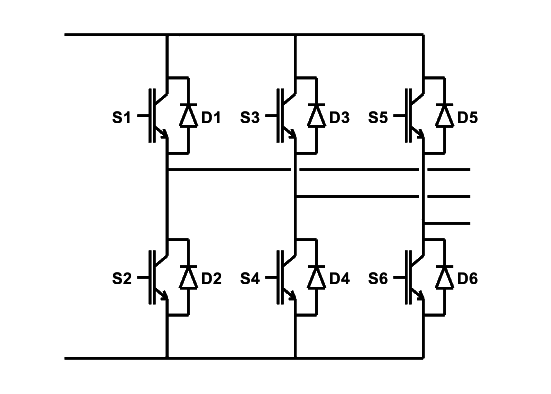

First we'll open the model

mdl = 'inverter_igbt';
open_system(mdl)

Set forward voltage as a ratio of DC voltage (e.g. 0.01 is 1% of DC voltage).

Vf_diode = 1e-3;
Vf_igbt = 1e-3;

Uncheck to disable the gate signal to an IGBT (recommend keeping everything checked to start with)

S1 = true; S3 = true; S5 = true;
S2 = true; S4 = true; S6 = true;

Uncheck to disable a diode (recommend keeping everything checked to start with). To observe voltage spikes caused by inductive flyback, uncheck all the diodes and set the Lload parameter (below) to 1e-3.

D1 = true; D3 = true; D5 = true;
D2 = true; D4 = true; D6 = true;

Set the PWM carrier frequency (modulation frequency is 50Hz)

pwm_carrier_frequency = 1000; % Hz

Set the PWM mode

 hpwm = find_system(mdl,'FindAll','on','LookUnderMasks','All','RegExp','on','Name','PWM Generator'); % find the PWM generator
 set(hpwm,'PWMMode','Continuous PWM (CPWM)')
 %set(hpwm,'PWMMode','Discontinuous PWM (DPWM)')

Set the load resistance and inductance (must be greater than zero - set inductance to 1e-8 to emulate a resistive load)

Rload = 1;      % ohms
Lload = 1e-3;   % henries

Simulate the system

Ts = 2e-5;
out = sim(mdl);

## Dynamic visualization of the system

In this section, we use MATLAB graphics to create a dynamic visualization of the simulation results. If you chose discontinuous PWM, the square associated with the clamped switch will fill black.

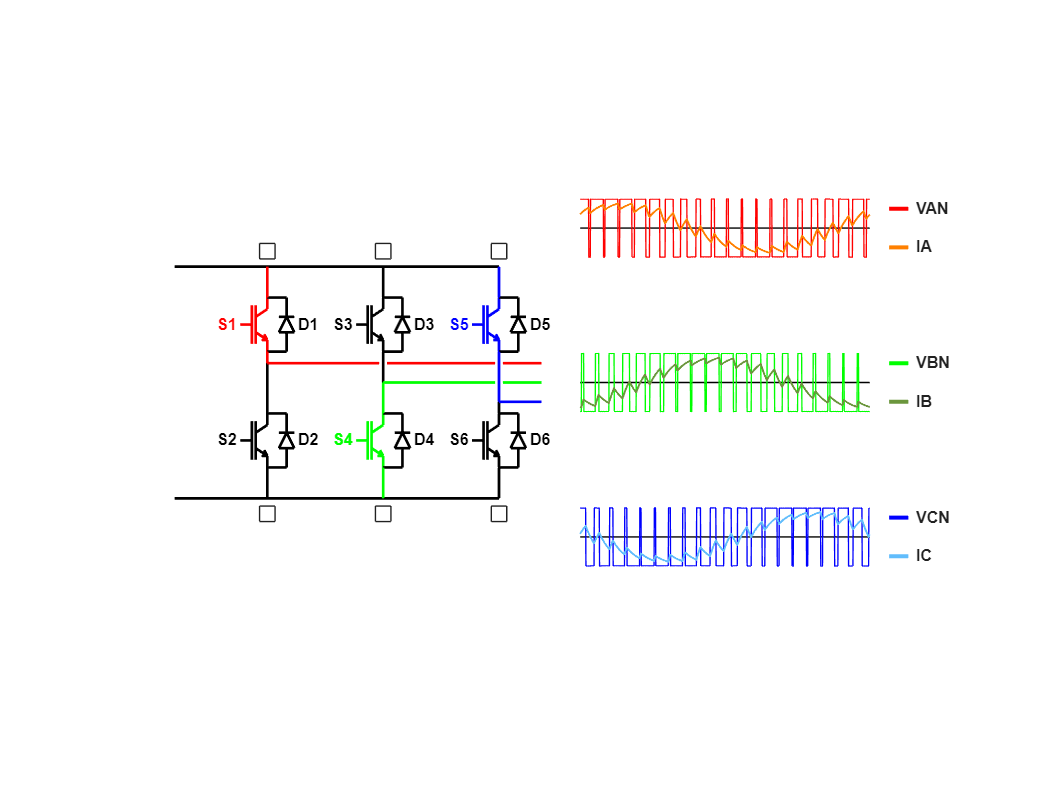

visualize_igbt_3phase

We hope you enjoyed this interactive learning resource - powered by MATLAB and Simscape Electrical !